
%% gmrt_wind_gust_davenport.m
% GMRT 45m Mesh Dish - Wind Gust Simulation using Davenport Filter


clear; clc; close all;

%% -----------------------
% INPUTS (change as needed)
% -----------------------
D       = 45;            % dish diameter (m)
R       = D/2;           % radius (m)
rho     = 1.15;          % air density (kg/m^3) - Khodad approx
Cd      = 0.60;          % mesh drag coefficient (dimensionless)
vn      = 3.15;          % mean wind speed (m/s)
z       = 23.16;         % antenna height (m)
z0      = 0.03;          % terrain roughness (m)
rcp_fac = 0.4;           % r_cp factor
rcp     = rcp_fac * R;   % effective moment arm (m)
Np      = 42;            % gear ratio axis-to-pinion
kT      = 4661;          % torque coefficient (Ns^2/m)
alpha   = 0.20;          % scale factor for gusts

% Davenport filter coefficients (given)
b_hd = [0.413 0.1762 -1.402 0.1762 0.413];
a_hd = [1 19.38 -40.79 19.38 1];

%% -----------------------
% STEADY FORCE & GUST GAIN
% -----------------------
A  = pi * D^2 / 4;                  % projected area (m^2)
kF = 0.5 * rho * Cd * A;            % steady force coeff
Fm = kF * vn^2;                     % steady force (N)

kappa = 1 / ((2.5 * log(z / z0))^2);
a     = sqrt(6 * kappa);
kf    = 2 * kF * a * vn^2;          % gust force gain (N)

Tm      = Fm * rcp;                 % steady torque (N*m)
Tw_RMS  = kf * rcp;                  % RMS gust torque (N*m)

% Pinion torque gain from gust velocity (from book eq. 5.36)
ki = (2 * kT * alpha) / (Np * vn);   % Nm/(m/s) — example calc

%% -----------------------
% TIME SERIES SIMULATION
% -----------------------
Ts   = 0.02;         % sampling time (s)
Tdur = 200;          % duration (s)
N    = round(Tdur / Ts);
t    = (0:N-1)' * Ts;

% Generate gust velocities Δv0(t)
wn = randn(N,1);                     % white noise
delta_v0 = filter(b_hd, a_hd, wn);   % apply Davenport filter
delta_v0 = delta_v0 / std(delta_v0); % normalize to unit std

% Force & Torque time histories
Fw_t = kf * delta_v0;                % gust force (N)
F_t  = Fm + Fw_t;                    % total force (N)
T_t  = F_t * rcp;                    % torque (N*m)

%% -----------------------
% OUTPUT RESULTS
% -----------------------
fprintf('--- GMRT Wind Gust Simulation ---\n');

--- GMRT Wind Gust Simulation ---


fprintf('Diameter D          = %.2f m\n', D);

Diameter D          = 45.00 m


fprintf('Projected area A    = %.2f m^2\n', A);

Projected area A    = 1590.43 m^2


fprintf('Steady force Fm     = %.2f N (%.2f kN)\n', Fm, Fm/1e3);

Steady force Fm     = 5444.46 N (5.44 kN)


fprintf('Gust gain kf        = %.2f N (%.2f kN)\n', kf, kf/1e3);

Gust gain kf        = 1604.59 N (1.60 kN)


fprintf('Steady torque Tm    = %.2f N*m (%.2f kN*m)\n', Tm, Tm/1e3);

Steady torque Tm    = 49000.17 N*m (49.00 kN*m)


fprintf('Gust torque RMS     = %.2f N*m (%.2f kN*m)\n', Tw_RMS, Tw_RMS/1e3);

Gust torque RMS     = 14441.35 N*m (14.44 kN*m)


fprintf('Check std(F_w)      = %.2f N (should be ~%.2f N)\n', std(Fw_t), kf);

Check std(F_w)      = NaN N (should be ~1604.59 N)


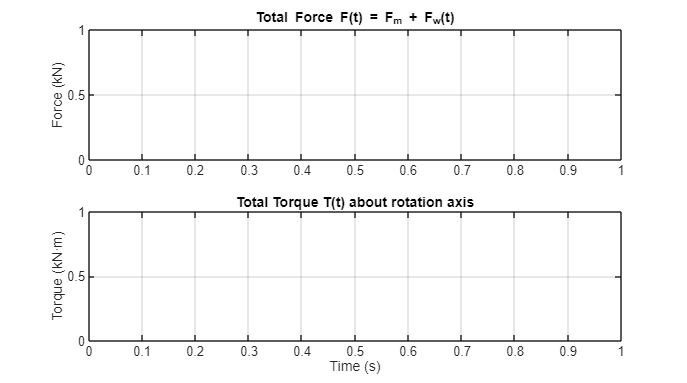


%% -----------------------
% PLOTS
% -----------------------
figure('Name','GMRT Wind Gust Simulation','NumberTitle','off','Position',[200 200 900 500]);
subplot(2,1,1);
plot(t, F_t/1e3); grid on;
ylabel('Force (kN)');
title('Total Force F(t) = F_m + F_w(t)');

subplot(2,1,2);
plot(t, T_t/1e3); grid on;
ylabel('Torque (kN·m)');
xlabel('Time (s)');
title('Total Torque T(t) about rotation axis');